# Unsupervised learning (let's find some patterns in our data)

[Return to introduction](matlab: edit S1_Introduction.mlx)

We'll start with unsupervised learning on a patient dataset. 

Researchers and physicians have been working for many years on determining biomarkers of certain diseases, such as cancer, that may help with prevention or diagnosis. With a disease like ovarian cancer, the earlier the disease can be detected, the better chance the patient has of recovering. 

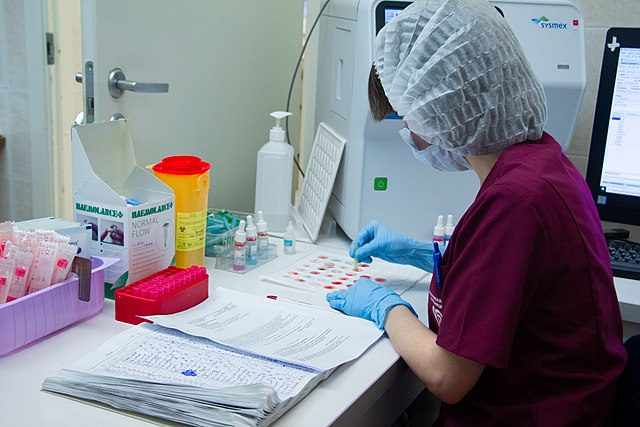

Human blood being tested in a [laboratory](https://commons.wikimedia.org/wiki/File:Human_Blood_Test.jpg). In this dataset, markers of cancer are measured from human blood serum. 

Proteins are one such biomarker that can be used. A [2002 study](https://pubmed.ncbi.nlm.nih.gov/11867112/) found that protein patterns in the serum of a patient's blood could determine whether or not they had ovarian cancer (i.e. the body will produce a given pattern of proteins when a cancer is attacking a patient's ovaries) [1]. A [2004 study](https://pubmed.ncbi.nlm.nih.gov/15163296/) studied thousands of different protein levels in patients with and without ovarian cancer [2]. 100 of those proteins are included in our data here for 216 patients (121 patients with cancer, and 95 without). This dataset comes embedded within MATLAB®, so we don't have to do anything fancy to get the data, simply use the function [`load()`](https://www.mathworks.com/help/matlab/ref/load.html). 

## 1: Load the data

load ovarian_dataset.mat

We are also going to adjust the shape of this data so it's more usable to us. Specifically, here we use the single quotation mark ([ctranspose](https://www.mathworks.com/help/matlab/ref/ctranspose.html)) to flip the shape of the matrices so that the data is in the correct structure for the functions we will use: 

ovarianTargets = ovarianTargets'; 
ovarianInputs = ovarianInputs'; 

You'll notice that two variables load in the workspace: `ovarianInputs` and `ovarianTargets`. The variable `ovarianInputs` contains information about the level of the 100 proteins in the serum as columns, and the 216 patient samples as rows. The variable `ovarianTargets` contains information about whether or not the patient has cancer. Each row is a patient, and patients with cancer have a value of 1 in column 1, while patients without cancer have a value of 0 in column 1. As we are starting with unsupervised learning, the computer doesn't need these "answers" to the test yet, so let's leave the `ovarianTargets` aside for now and focus on inputs. 

## 2: Find clusters in the data

Let's use unsupervised learning to find some natural patterns in this patient dataset. We'll start by trying to find some "clusters" or groupings in our data. A common method for this is called [k-means clustering](https://www.mathworks.com/help/stats/kmeans.html), where we simply assign observations to a specific number of groups. The first step in [k-means clustering](https://en.wikipedia.org/wiki/K-means_clustering) is to determine how many groups you want to find. There are several ways mathematically to determine the optimal number, and it is typically recommended to try different values of k. These methods can quickly become complicated, but we can also rely on any prior knowledge we have about the dataset. We can think about how many clusters would make sense in our analysis of the data. In this case, we expect some of the patients to have cancer and some of the patients to not have cancer. So, let's try using 2 groups in our k-means clustering. Later, we will see if these groups align with patients who do or do not have cancer.  

The math behind this model is beyond our scope, but basically, if we ask the computer to find 2 groups in a set of data, it will find the optimal way to assign the given data to 2 separate groups (if you're curious, it depends on the distances between points)! Let's try this, and try dividing our patient data into 2 clusters. 

  Type the following code into the code block and run this cell: 

The function [`kmeans()` ](https://www.mathworks.com/help/stats/kmeans.html)takes in the data, and the number of groups you want, as inputs. 

  Find the size of `groups` by running `size(groups)`: 

The variable `groups` is an array where each patient is represented by a single value (1 or 2), which indicates which group they have been assigned to by the clustering. 

## 3: Reduce the dimensions of the data 

If we wanted to visualize the two groups, we'd have a tough time, because there are 100 "predictors" or variables in our table, and it's really hard to visualize data in any dimension past the third dimension. This is where the concept of "dimensionality reduction", reducing the number of dimensions, or axes, we need to describe our data, comes into play. 

A really common form of this is [**principal component analysis**](https://www.mathworks.com/help/stats/pca.html), or [PCA](https://en.wikipedia.org/wiki/Principal_component_analysis). 

In PCA, we transform our variables onto a new set of axes, building a new coordinate system. If you imagine a basic 2 dimensional data set, like this: 

x = [0 1 2 3 4 5];
y = [0 1 1.8 3.1 4 5; 0.1 1.1 2.2 2.9 4.2 4.7];

scatter(x,y)
hold on
plot(x,x)
hold off

xlim([0 5])
ylim([0 5])

By way of demonstration, a line that describes this data is drawn as the diagonal line through the origin (plotted here). In PCA, this line would be called the first principal component (called a PC). Just think of this as "the line through my data that describes it the best". The second principal component is always a line orthogonal (perpendicular) to the first. 

That might look like this (note the axes have changed slightly): 

scatter(x,y)
hold on 
plot ([-5 5],[-5 5])
plot ([-5 5],[5 -5])
hold off

xlim([-2 5])
ylim([-2 5])
axis square
legend(["","","PC1","PC2"],"Location","best")

These 2 lines become a new coordinate system, on which we project all of our original data points (so imagine rotating these new axes to make a coordinate system like what we're used to seeing, and then plotting the original data points along them. That's PCA!). Each point on PC1 is a combination of the original values of x and y (which is given by the slope of PC1). So each PC tells us how important each variable is to describing it (it's composed of a % of each variable). We keep creating principal components until we have the same number of principal components as we did initial variables (in this example, we, therefore, have 2 PCs that explain x and y-- but with our patient data, we'll have 100). The point of PCA is to find a couple of axes that explain most of the variation in the data, so we can create an interpretable or visualizable model that is plotted in two dimensions. 

So, the computer determines which coordinates explain the majority of the variance in the data (or differences of each data point from a common mean, or that diagonal line in the above example) and orders the data according to which coordinates explain the most variance. These coordinates are called the principal components. We can use the MATLAB [`pca()`](https://www.mathworks.com/help/stats/pca.html) function to perform PCA on data. 

Try: 

[coeffs,score,~,~,expvar] = pca(ovarianInputs);

There are multiple outputs here: in position 1 we are outputting the principal components themselves. In position 2 we are outputting the principal component scores--- you can see this matrix is the same size as `ovarianInputs`. It contains all the same data but just transformed onto our new axes (these are described by `coeffs`). Finally, position 5 outputs the amount of variance explained by each principal component. 

  Check out how much variance is explained by typing `expvar` into the block below and running the section: 

Principal components are ordered in order of how much of the variance in the data they explain. So PC1 explains 81.48% of the variance, PC2 explains 11.45%, and so on. 

We can visualize the explained variance using a [Pareto](https://www.mathworks.com/help/matlab/ref/pareto.html) [chart](https://en.wikipedia.org/wiki/Pareto_chart). 

  Run `pareto(expvar)`: 

Add explanatory x and y-labels: 

xlabel ("Principal Component")
ylabel ("Percentage of variance explained")

We can see the amount of variance explained by each component, and the line tells us the cumulative variance explained by the components. You can see that about 90% of the data's variance is explained by the first two principal components--that's a lot! That means we can reasonably look at our data in two dimensions, rather than 100. These dimensions are PC1 and PC2. 

## 4: Visualize new axes of data

Let's plot the data along the first two principal components (recall that the transformed data is stored as `scores`, and each column represents a PC). We will plot the two principal components against each other using [`scatter()`](https://www.mathworks.com/help/matlab/ref/scatter.html). 

scatter(score(:,1), score(:,2))

  Add an x-label by running` xlabel("PC1")`:

  Add a y-label for PC2: 

What if we plot in 3D? We can create a 3D scatter plot using [`scatter3()`](https://www.mathworks.com/help/matlab/ref/scatter3.html) and providing the first 3 principal components as inputs: 

scatter3(score(:,1), score(:,2), score(:,3))
xlabel ("PC1")
ylabel ("PC2")
zlabel ("PC3")

 Does the 3rd dimension add much information, or is the distribution of the data pretty well defined by the first two principal components? 

We've reduced the dimensions of our data and visualized the top two dimensions-- awesome! Now let's go back and apply our groupings to the PCA data and see what we see. 

We will scatter the first two principal components, and color by group using the function [`gscatter()`](https://www.mathworks.com/help/stats/gscatter.html): 

gscatter(score(:,1), score(:,2), groups)

  Add appropriate x and y labels that explain which principal components are being plotted: 

We have two clear groups here, which is what we expect from k-means clustering.  

## 5: Apply our clusters to the reduced dimensionality data 

Does this grouping of patients correspond to whether or not these patients have ovarian cancer? 

We can use the [`crosstab()`](https://www.mathworks.com/help/stats/crosstab.html) function to determine how our clusters relate to some categories. 

  You can always use the `doc` or `help` functionality to learn more about a function. Run `doc crosstab` to learn more about this function: 

We want to compare our clusters to whether or not each patient has cancer. Therefore, we'll need to compare our clusters to `ovarianTargets`. We'll first turn `ovarianTargets` into a categorical array called `diagnosis`.  We're only going to use the first column of this matrix (the second is redundant as column 1 contains a 1 if the patient has cancer/ 0 if not and column 2 just contains the opposite). Run:

diagnosis = categorical(ovarianTargets(:,1));

Then, we can perform the cross-tabulation of the groups we made (2 clusters) and the diagnosis. We'll then visualize this cross-tabulation as a [heatmap](https://www.mathworks.com/help/matlab/ref/heatmap.html). 

cts = crosstab(groups, diagnosis);
heatmap (cts,"XDisplayLabels",["cancer", "no cancer"],"YDisplayLabels",["Cluster 1" "Cluster 2"])

`crosstab()` takes as input the groups you made via k-means clustering and the groups of the real data (in this case the diagnosis). It returns a matrix of how many patients were classified in each category. 

 How well do you think the k-means clustering matches up with the patient diagnosis?

 In this case, one group identified mostly people with cancer, and the other group identified patients mostly without cancer. There is some error here of course--it seems like if a patient is classified in the "looks like cancer" group, they have about a 70% chance of having cancer. Meanwhile, if someone is classified in the "looks like no cancer" group, they have about a 98% chance of not having cancer. If this was used as patient classification criteria, it is important to note that there is a higher false positive rate (telling people they might have cancer when they don't) than a false negative rate (telling people they don't have cancer when they do). This is discussed further in the next section.  

It seems like the k-means clustering did a pretty good job of finding underlying patterns in the data that group patients by whether they have ovarian cancer or not. We only really needed one line of code (grouping the patients into two groups using k-means clustering) to have really strong predictive power and determine if patients might have cancer or not. You can imagine how having this kind of predictive power would become really important in a clinical setting! 

This kind of process of clustering data and then reducing dimensionality to visualize clusters is used in countless scientific papers where many variables are studied across many samples! In the next section, we will take this same data and use supervised learning on it. Our goal will be to build a model such that if we fed new patient serum data into the computer, it would be able to spit out whether or not this patient is likely to have ovarian cancer. This can help identify the disease early, reduce human error, and serve as a first stop before more invasive tests are performed to confirm the disease. 

## Additional Resources

You can explore further into clustering algorithms for machine learning in [Machine Learning Methods: Clustering](https://www.mathworks.com/matlabcentral/fileexchange/135381-machine-learning-methods-clustering).

## References 

[1]  Petricoin EF, Ardekani AM, Hitt BA, Levine PJ, Fusaro VA, Steinberg SM, Mills GB, Simone C, Fishman DA, Kohn EC, Liotta LA. Use of proteomic patterns in serum to identify ovarian cancer. Lancet. 2002 Feb 16;359(9306):572-7. doi: 10.1016/S0140-6736(02)07746-2. PMID: 11867112.

$\uparrow$ Return to text

[2] Conrads TP, Fusaro VA, Ross S, Johann D, Rajapakse V, Hitt BA, Steinberg SM, Kohn EC, Fishman DA, Whitely G, Barrett JC, Liotta LA, Petricoin EF 3rd, Veenstra TD. High-resolution serum proteomic features for ovarian cancer detection. Endocr Relat Cancer. 2004 Jun;11(2):163-78. doi: 10.1677/erc.0.0110163. PMID: 15163296.

$\uparrow$ Return to text

[Go to next section (Supervised learning)](matlab: edit S3_Supervised_learning.mlx)

[Return to introduction](matlab: edit S1_Introduction.mlx)